# Script to evaluate the "18 m/s Hurdles" for the LAC Summer Games 2025

**Task** 

Get the best possible wind preview (2s) by improving the baseline lidar data processing (LDP_v3)!

**Results 4BeamPulsed**

v3: Cost for Summer Games 2025 ("18 m/s hurdles"):  0.515998 m/s 

**Results CircularCW**

v3: Cost for Summer Games 2025 ("18 m/s hurdles"):  0.463842 m/s 

## 1. Setup

clearvars; close all; clc;
% select LDP function
MyLDPfunction       = @LDP_Bolivia;
plot_flag = true; % flag for plotting intermediate results

% select LidarType
% for LidarType = ["4BeamPulsed" "CircularCW"]
for LidarType = "CircularCW"
    % LidarType           = '4BeamPulsed'; % [4BeamPulsed/CircularCW]
    LidarType = char(LidarType);

    % Seeds (can be adjusted, but will provide different results)
    nSeed               = 6;                        % [-]	    number of stochastic turbulence field samples
    Seed_vec            = (1:nSeed)+18*100;         % [-]  	    vector of seeds


    % Parameters postprocessing (can be adjusted, but will provide different results)
    t_start             = 60;                       % [s] 	    ignore data before for STD and spectra
    % t_start             = 0;                       % [s] 	    % error is reduced only for 4BeamPulsed
    TMax                = 660;                      % [s]       total run time
    DT                  = 0.01;                     % [s]       time step
    time                = (0:DT:TMax)';             % [s]       time vector

    % Parameter for Cost (Summer Games 2025)
    tau                 = 2;                        % [s]       time to overcome pitch actuator, from Example 1: tau = T_Taylor - T_buffer, since there T_filter = T_scan = 0

    switch LidarType
        case '4BeamPulsed'
            % configuration from LDP_v1_4BeamPulsed.IN and FFP_v1_4BeamPulsed.IN
            LDP.NumberOfBeams       = 4;            % [-]       Number of beams measuring at different directions
            LDP.AngleToCenterline   = 19.176;       % [deg]     Angle around centerline
            LDP.IndexGate           = 6;            % [-]       IndexGate
            LDP.FlagLPF             = 1;            % [0/1]     Enable low-pass filter (flag)
            % LDP.omega_cutoff        = 0.13;         % [rad/s]   Corner frequency (-3dB) of the low-pass filter
            LDP.omega_cutoff        = 0.14;         % [rad/s]   Corner frequency (-3dB) of the low-pass filter
            LDP.T_buffer            = 0.2;          % [s]       Buffer time for filtered REWS signal
        case 'CircularCW'
            % configuration from LDP_v1_CircularCW.IN and FFP_v1_CircularCW.IN
            LDP.NumberOfBeams       = 50;           % [-]       Number of beams measuring at different directions
            LDP.AngleToCenterline   = 15;           % [deg]     Angle around centerline
            LDP.IndexGate           = 1;            % [-]       IndexGate
            LDP.FlagLPF             = 1;            % [0/1]     Enable low-pass filter (flag)
            LDP.omega_cutoff        = 0.20;         % [rad/s]   Corner frequency (-3dB) of the low-pass filter
            LDP.T_buffer            = 4.2;          % [s]       Buffer time for filtered REWS signal
    end

## 2. Data postprocessing 

    % Files (should not be be changed)
    SimulationFolderLAC     = 'solis_lidar_data';
    % Allocation
    MAE     = NaN(1,nSeed); % mean absolute error [m/s]

    % Loop over all seeds
    % for iSeed = 1:nSeed
    for iSeed = 1
        % Load, interpolate and extrapolate the simulated data
        Seed                                = Seed_vec(iSeed);
        WindFileName                        = ['URef_18_Seed_',num2str(Seed,'%02d')];
        SolisResultFile                     = fullfile(SimulationFolderLAC,[WindFileName,'_lidar_data_',LidarType,'.csv']);
        SolisData                           = readtable(SolisResultFile);
        
        % replace zeros of lineOfSightWindSpeed by last corresponding beam lineOfSightWindSpeed
        data_aux = SolisData(:,["time" "beamID" "lineOfSightWindSpeed"+LDP.IndexGate "isValid"+LDP.IndexGate]);
        data_aux.index = (1:height(data_aux))';
        idx_zero = true;
        while nnz(idx_zero)
            idx_zero = data_aux.(3) == 0 & data_aux.index - 4 >0;
            data_zeros = data_aux(idx_zero,:);
            data_aux(data_zeros.index,3) = data_aux(data_zeros.index - 4,3);
            data_aux(data_zeros.index,4) = data_aux(data_zeros.index - 4,4);
        end
        SolisData.("lineOfSightWindSpeed"+LDP.IndexGate) = data_aux.(3);
        SolisData.("isValid"+LDP.IndexGate) = data_aux.(4);

        beamID                              = interp1(SolisData.time,SolisData.beamID,time,'previous','extrap');
        isValid                             = interp1(SolisData.time,SolisData.("isValid"+LDP.IndexGate),time,'previous','extrap');
        lineOfSightWindSpeed                = interp1(SolisData.time,SolisData.("lineOfSightWindSpeed"+LDP.IndexGate),time,'previous','extrap');

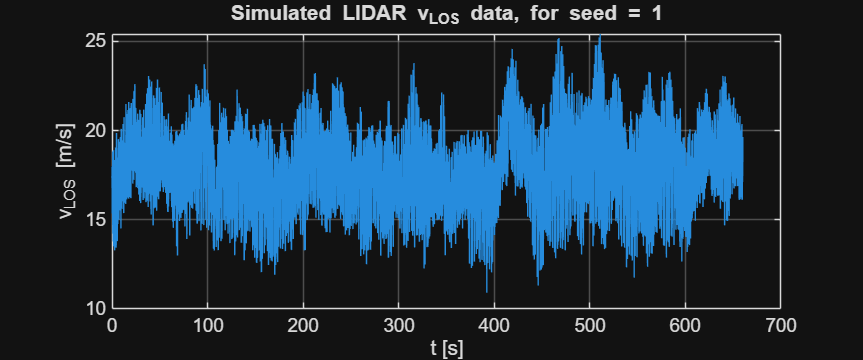

        % plots of simulated LIDAR data
        if plot_flag
            idx = logical(isValid);
            f_width = 1200;f_height = 500;
            fontsize = 14;

            f = figure;
            f.Position([3 4]) = [f_width f_height];

            plot(time(idx),lineOfSightWindSpeed(idx))
            xlabel('t [s]'); ylabel("v_{LOS} [m/s]")
            title(['Simulated LIDAR v_{LOS} data, for seed = ',num2str(iSeed)])

            ax = gca;
            ax.FontSize = fontsize;
            grid on
        end

        % Get REWS from the wind field
        RewsFile                 	        = ['TurbulentWind\URef_18_Seed_',num2str(Seed,'%02d'),'.csv'];
        RewsData                            = readtable(RewsFile);

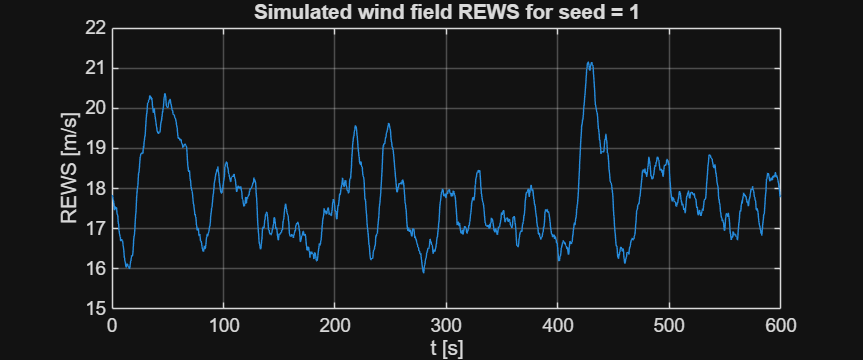

        % plot of simulated wind field
        if plot_flag
            f = figure;
            f.Position([3 4]) = [f_width f_height];

            plot(RewsData.time,RewsData.REWS)
            xlabel('t [s]'); ylabel("REWS [m/s]")
            title(['Simulated wind field REWS for seed = ',num2str(iSeed)])

            ax = gca;
            ax.FontSize = fontsize;
            grid on
        end

        % processed REWS data
        REWS_WindField                      = interp1([RewsData.time;RewsData.time+600],[RewsData.REWS;RewsData.REWS],time); % REWS is circular
        REWS_WindField_shifted              = interp1([RewsData.time;RewsData.time+600],[RewsData.REWS;RewsData.REWS],time+tau);

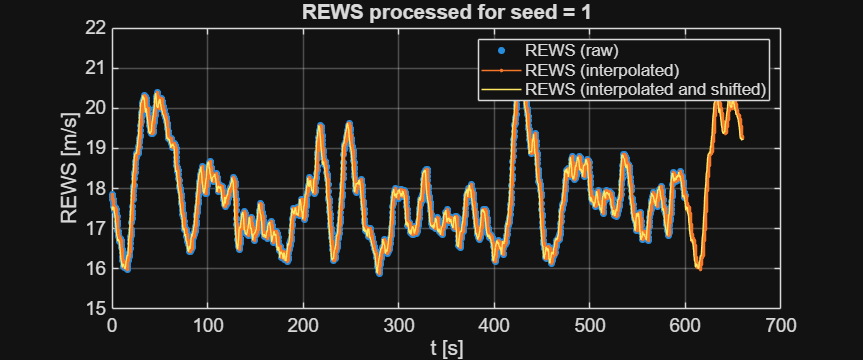

        % plot of REWS processed
        if plot_flag
            f = figure;
            f.Position([3 4]) = [f_width f_height];

            plot(RewsData.time,RewsData.REWS,".",MarkerSize=16)
            hold on
            plot(time,REWS_WindField,".-",MarkerSize=8)
            plot(time,REWS_WindField_shifted)
            hold off
            xlabel('t [s]'); ylabel("REWS [m/s]")
            legend('REWS (raw)','REWS (interpolated)','REWS (interpolated and shifted)',Interpreter='none')
            title(['REWS processed for seed = ',num2str(iSeed)])

            ax = gca;
            ax.FontSize = fontsize;
            grid on
        end

        % Calculate REWS from the lidar data
        clear(func2str(MyLDPfunction)) % clearing all persistent variables from previous call
        [REWS,REWS_f,REWS_b]                = MyLDPfunction(time,isValid,beamID,lineOfSightWindSpeed,DT,LDP);

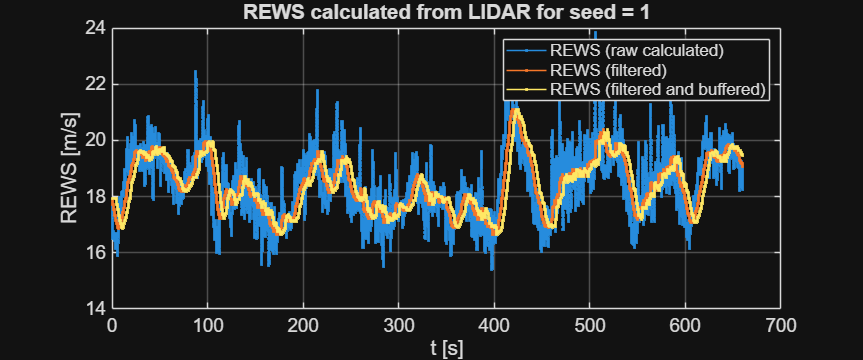

        % plot of REWS calculated
        if plot_flag
            f = figure;
            f.Position([3 4]) = [f_width f_height];

            plot(time,REWS,".-")
            hold on
            plot(time,REWS_f,".-")
            plot(time,REWS_b,".-")
            hold off
            xlabel('t [s]'); ylabel("REWS [m/s]")
            legend('REWS (raw calculated)','REWS (filtered)','REWS (filtered and buffered)',Interpreter='none')
            title(['REWS calculated from LIDAR for seed = ',num2str(iSeed)])

            ax = gca;
            ax.FontSize = fontsize;
            grid on
        end

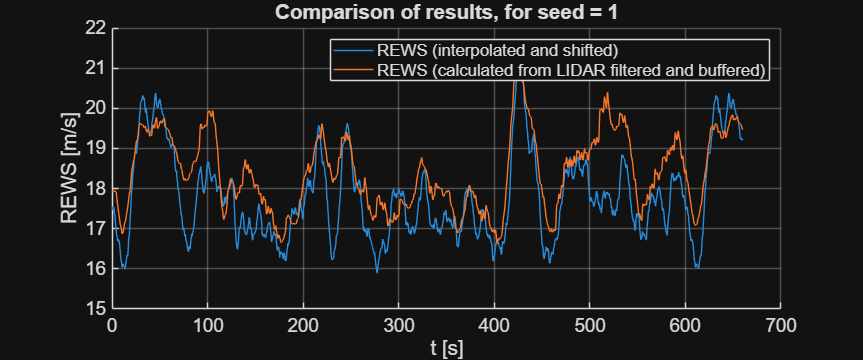

        % plot a comparison between given REWS and calculated REWS from LIDAR
        if plot_flag
            f = figure;
            f.Position([3 4]) = [f_width f_height];

            hold on
            plot(time,REWS_WindField_shifted)
            plot(time,REWS_b)
            hold off
            xlabel('t [s]'); ylabel("REWS [m/s]")
            legend('REWS (interpolated and shifted)','REWS (calculated from LIDAR filtered and buffered)',Interpreter='none')
            title(['Comparison of results, for seed = ',num2str(iSeed)])

            ax = gca;
            ax.FontSize = fontsize;
            grid on
        end

## 3. Calculation of MAE

        % Calculate mean absolute error
        Error = REWS_WindField_shifted-REWS_b; % error is REWS from wind field shifted minus REWS from lidar filtered and buffered.
        % Error = REWS_WindField_shifted-REWS_f; % error is increased!
        idx = time>=t_start; % only consider error after t_start
        error_without_detrend = Error(idx);
        error_with_detrend = detrend(Error(idx),'constant'); % remove mean value before calculating MAE

        % isequal(error_without_detrend-mean(error_without_detrend),error_with_detrend); % verification that detrend removes the mean value 
        MAE(iSeed)                          = mean(abs(error_with_detrend)); % or use built-in mae(error_with_detrend)

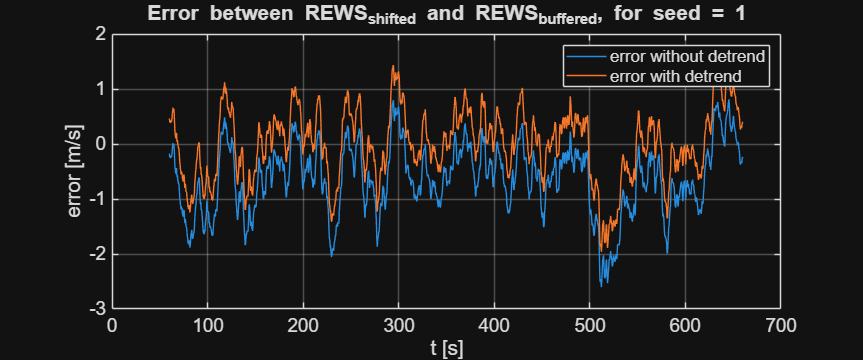

        % plot of errors
        if plot_flag
            f = figure;
            f.Position([3 4]) = [f_width f_height];

            plot(time(idx),error_without_detrend)
            hold on
            plot(time(idx),error_with_detrend)
            hold off

            xlabel('t [s]'); ylabel("error [m/s]")
            legend('error without detrend','error with detrend')
            title(['Error between REWS_{shifted} and REWS_{buffered}, for seed = ',num2str(iSeed)])

            ax = gca;
            ax.FontSize = fontsize;
            grid on
        end

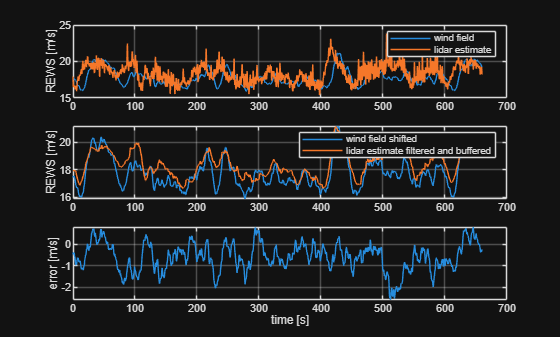

        % plot REWS for absolute error
        if plot_flag
            figure('Name',['REWS seed ',num2str(Seed)])

            subplot(311)
            hold on; grid on; box on
            plot(time,  REWS_WindField);
            plot(time,  REWS);
            ylabel('REWS [m/s]');
            legend('wind field','lidar estimate')

            subplot(312)
            hold on; grid on; box on
            plot(time,  REWS_WindField_shifted);
            plot(time,  REWS_b);
            ylabel('REWS [m/s]');
            legend('wind field shifted','lidar estimate filtered and buffered')

            subplot(313)
            hold on; grid on; box on
            plot(time,  Error);
            ylabel('error [m/s]');
            xlabel('time [s]')
        end
    end

## 4. Calculation of cost

    Cost                        = mean(MAE,"omitmissing");
    fprintf('Cost for Summer Games 2025 ("18 m/s hurdles" for LIDAR %s):  %f \n',LidarType,Cost);
end

Cost for Summer Games 2025 ("18 m/s hurdles" for LIDAR CircularCW):  0.508958 
